# CISC271, Winter 2024, Week 7, Day 1B: k-Means for Iris Data and Graphs

## Applying kmeans to Iris dataset

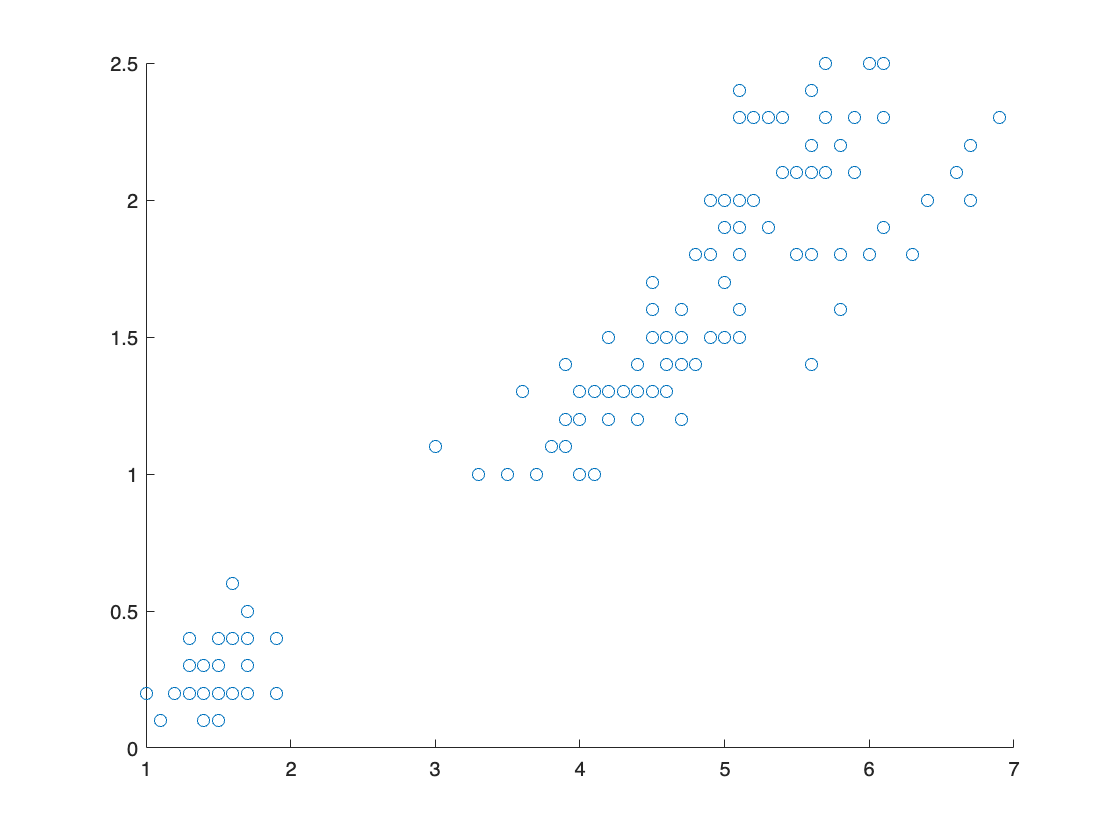

% Load the data from the Matlab repository; 
% extract the sepal length and sepal width as column-oriented data 
load fisheriris
xMat = meas(:,3:4);

% Since this data is already in 2D, we don't have to reduce it before
% clustering but, we should visualize it first to determine k.
scatter(xMat(:,1), xMat(:,2))

%Q: What do you notice?

% Use the builtin function for K-means clustering 
[clustersIris, centroidsIris] = kmeans(xMat, 2);

colorMat = zeros(150,2);
colorMat(clustersIris == 1, 1) = 1; % assign group 1 to red
colorMat(clustersIris == 2, 3) = 1; % assign group 2 to blue

scatter(xMat(:,1), xMat(:,2), 60, colorMat, '*');
%plot the centroids
hold on;
scatter(centroidsIris(:,1), centroidsIris(:,2), 100, 'k.');
hold off;

% If we know what the label of each point should be, we can calculate
% accuracy, sensitivity etc.

% Find the line that separates the clusters
% Normal vector, unscaled
vectorsIris = centroidsIris';
wVecRaw = vectorsIris(:,1) - vectorsIris(:,2);
wVec = wVecRaw/norm(wVecRaw)

wVec =     0.9242
    0.3820


% Mean vector and bias scalar
meanVec = mean(vectorsIris, 2);
bVal = -dot(wVec, meanVec)

bVal = -3.3368

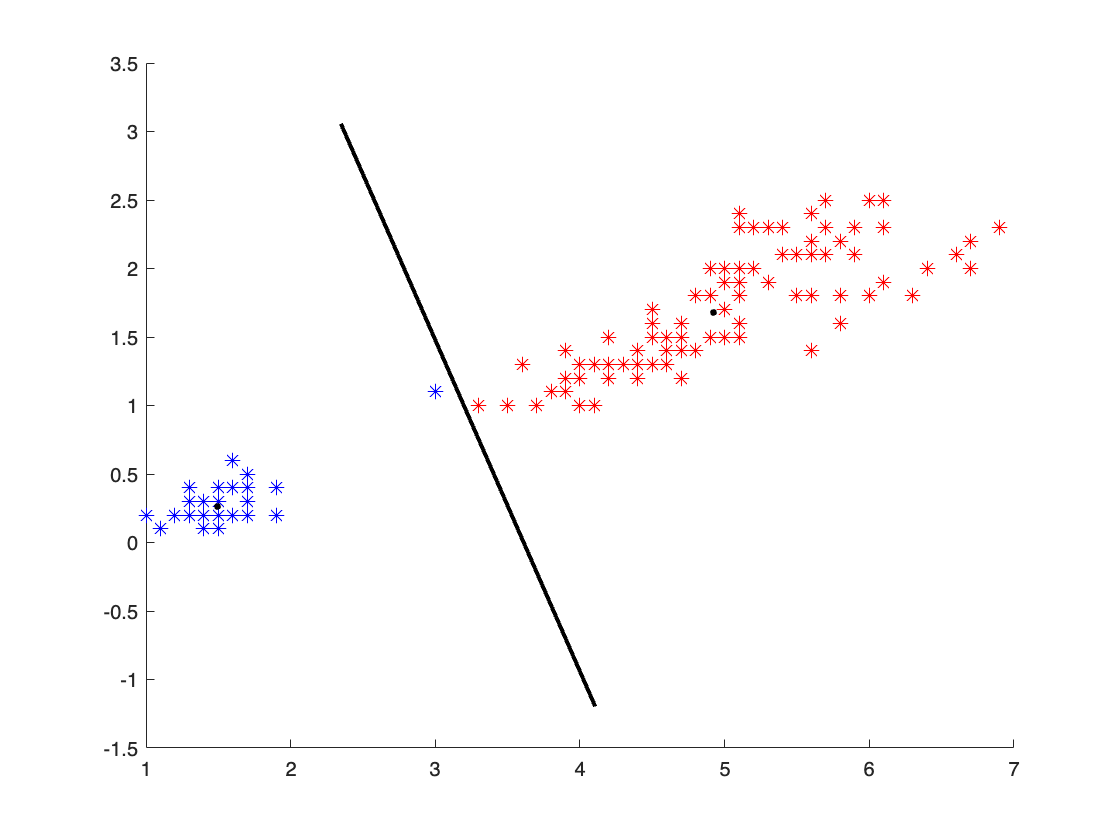

% Augment the normal with the bias scalar and plot the separation
wAugVec = [wVec ; bVal];
plotline(wAugVec, 'k');

## Applying kmeans to graphs

% Load the adjacency matrix of the test edges
A = load("testmat.txt");
% Find the Laplacian matrix of the graph
L = diag(sum(A,2)) - A;
% Compute and sort the spectral decomposition
[E,D] = eig(L, 'vector');
[~,dIndex] = sort(D, 'ascend');
D = D(dIndex);
E(:,dIndex) = E;
% Feidler vector is of the second least eigenvalue
fVector = E(:,2);
disp(fVector')

   -0.2589   -0.1712    0.2655    0.2591    0.2020   -0.2158    0.2515   -0.2525   -0.2525    0.1701    0.1540    0.1647   -0.1658   -0.1751   -0.2525    0.2637    0.2602   -0.2033   -0.2525    0.2095



% Cluster the Fiedler vector into 2 sets
kRaw = kmeans(fVector, 2, 'Replicates', 100);
% Convert 1/2 into -1/1
kClusters = sign(kRaw - 1.5)

kClusters =      1
     1
    -1
    -1
    -1
     1
    -1
     1
     1
    -1


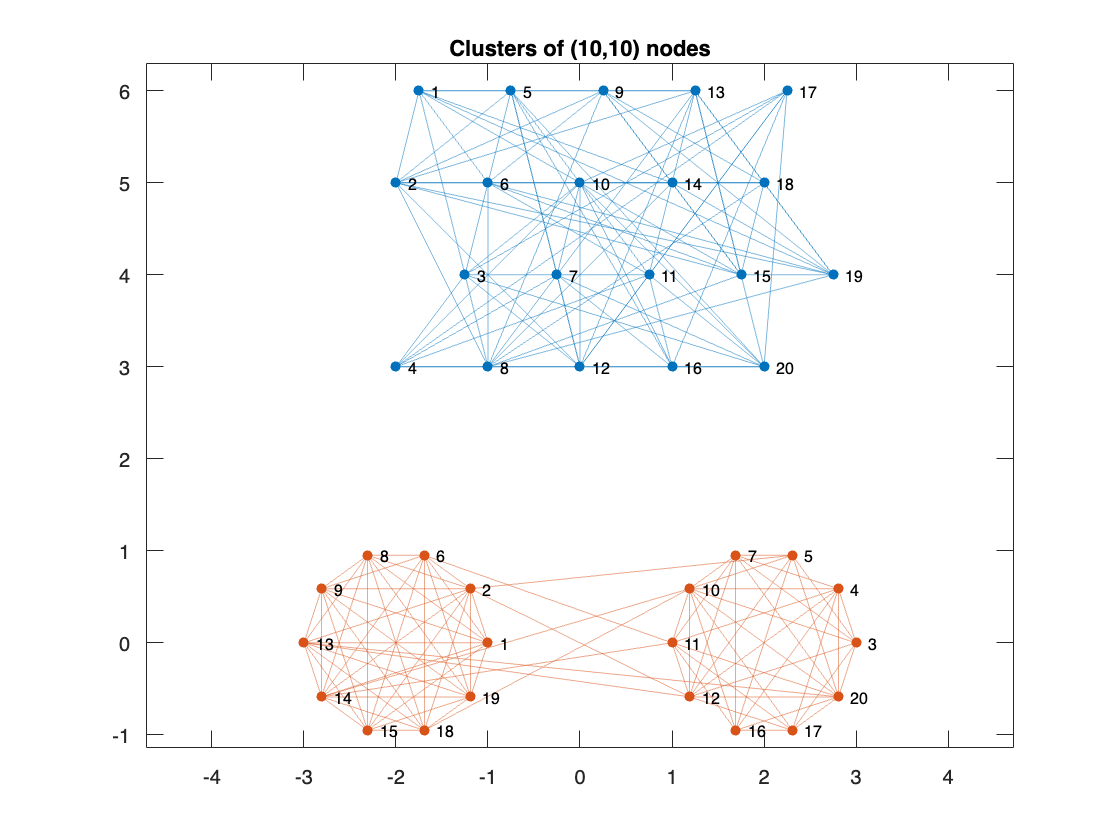

% Plot the results
plot271a1(A, kClusters);